# P19 B:  Impedancia de un circuito RC

## **Trabajo Previo**

**Diego Nicolas Lobato**

C=10^-7;
	R=2100;
	v=30:1:3000;
	
	for i=1:length(v)
	Z(i)= sqrt(R^2 + (1/(2*pi*v(i)*C))^2);
	phi(i) = atan(1/(2*pi*v(i)*R*C));
    end

    phig=phi.*180/pi

phig =    87.7332   87.6577   87.5822   87.5068   87.4313   87.3559   87.2804   87.2050   87.1296   87.0542   86.9788   86.9034   86.8280   86.7527   86.6773   86.6020   86.5267   86.4513   86.3760   86.3007   86.2255   86.1502   86.0750   85.9997   85.9245   85.8493   85.7741   85.6989   85.6237   85.5486   85.4734   85.3983   85.3232   85.2481   85.1731   85.0980   85.0230   84.9479   84.8729   84.7979   84.7230   84.6480   84.5731   84.4982   84.4233   84.3484   84.2735   84.1987   84.1239   84.0491


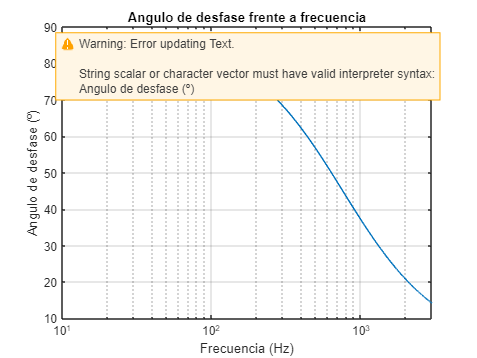

	
	loglog(v,Z)
	title('Modulo de la Impedancia frente a frecuencia')
	xlabel('Frecuencia (Hz)')
	ylabel('Modulo de la impedancia (k$\Omega$)',Interpreter='latex')
	grid on
	
    figure

	semilogx(v,phig)
	title('Angulo de desfase frente a frecuencia')
	xlabel('Frecuencia (Hz)')
	ylabel('Angulo de desfase (º)', 'Interpreter','latex')
	
	grid on